# MATLAB Simulation & Symbolic Algebra Project

**Joseph Pym**

## Welcome

This project was a first-year coursework I took whilst at university, as part of a module introducing us to MATLAB and LaTeX. The coursework was marked 66% on the two MATLAB tasks, and 33% on the LaTeX write-up. The submitted piece of work (the LaTeX write-up) is [available here](https://jep00.github.io/docs/work/matlabsim.pdf); the GitHub repository is [here](https://github.com/jep00/matlabsim/).

I achieved 90% on the work, and whilst I have learnt a lot of coding techniques and skills since, it is, in my opinion, a good effort for my first major piece of coding. 

*n.b.* As the work was not designed for online viewing, rather just the screenshots of plots were assessed, I'd strongly recommend viewing the final write-up, too, to assess the work.

## Task One: Collision-less Brownian Motion

Task One involved the following tasks:

- a) Plot 'walls' of a container and place up to 500 identical randomly distributed particles within the centre area (radius 100 units). Assign a random value of speed and direction to each particle individually (initial velocity) in a range, such as 10 to 50 units per time interval.

- b) Start your time 'ticking' in discreet intervals (dt) and calculate and plot the updated positions of particles every n time steps. Save every  nth screenshot of the plot for your report.

- c) When a particle hits the 'walls'  it must be reflected to bounce back without any loss of energy; to demonstrate this, generate a few particles inside and plot the traces of their trajectories as thin solid lines behind. Stop the simulation after some collisions and save the resulting figure.

- d) The code should have the ability to switch on 'gravity': under the action of which, the particles must start to fall down (negative y-direction) and repeatedly bounce against the 'floor'.

- e) Finally, incorporate a 'loss of energy' function (e.g. at each collision, the balls should lose x% of its speed).

- f) On a different plot, show how total energy stays the same in c) and decays in e). What about d)? Comment on your findings.

### Tasks a) to c)

The following code will first initialise our conditions randomly, for the number of particles $N$, a random angle to 'set off at' $\theta$, a radius within which the points will generate within $r$, and finally converting $\theta$ into polar coordinates, with labels $x$ and $y$.

close all                    % Closes all current figures
% I have named a lot of the variables with
% a after to avoid issues with future code

% Initialisations

figure(1)                    % Opens a new plot

Na   = randi([100 500],1,1); % Generates particles
theta= 360*rand(Na,1,1);     % Random angle between 0 and 360 deg
ra   = 100*rand(Na,1,1);     % Random radius less than 100 units
xa   = ra.*cosd(theta);
ya   = ra.*sind(theta);      % Polar coordinates

Each of $\theta$, $r$, $x$, and $y$ are vectors length $N$. We then use the code below to plot the points as 'balls', setting the axis from -500 to 500 in both the $x$ and $y$ directions. We add a title to the plot, too.

ha   = plot(xa,ya,'o');      % Plotting the graph
axis manual
axis([-500 500 -500 500])
daspect([1 1 1])
title('Task 1a')             % Plot title

Next, we assign each point a random velocity, such that $10\le v\le 50$ for each point, multiplying this by the horizontal and vertical components of the polar coordinates to find the velocity components.

va   = 40*rand(Na,1,1)+10;   % Random veloicty 10 ? v ? 50
vxa  = va.*cosd(theta);      % Horizontal velocity component
vya  = va.*sind(theta);      % Vertical velocity component

Reset 'time' and define the 'time-step'. Under time = 250, we update the time and coordinates, plotting the new positions. We save an image of the plot (for use in our LaTeX write-up) at each step of 10. 

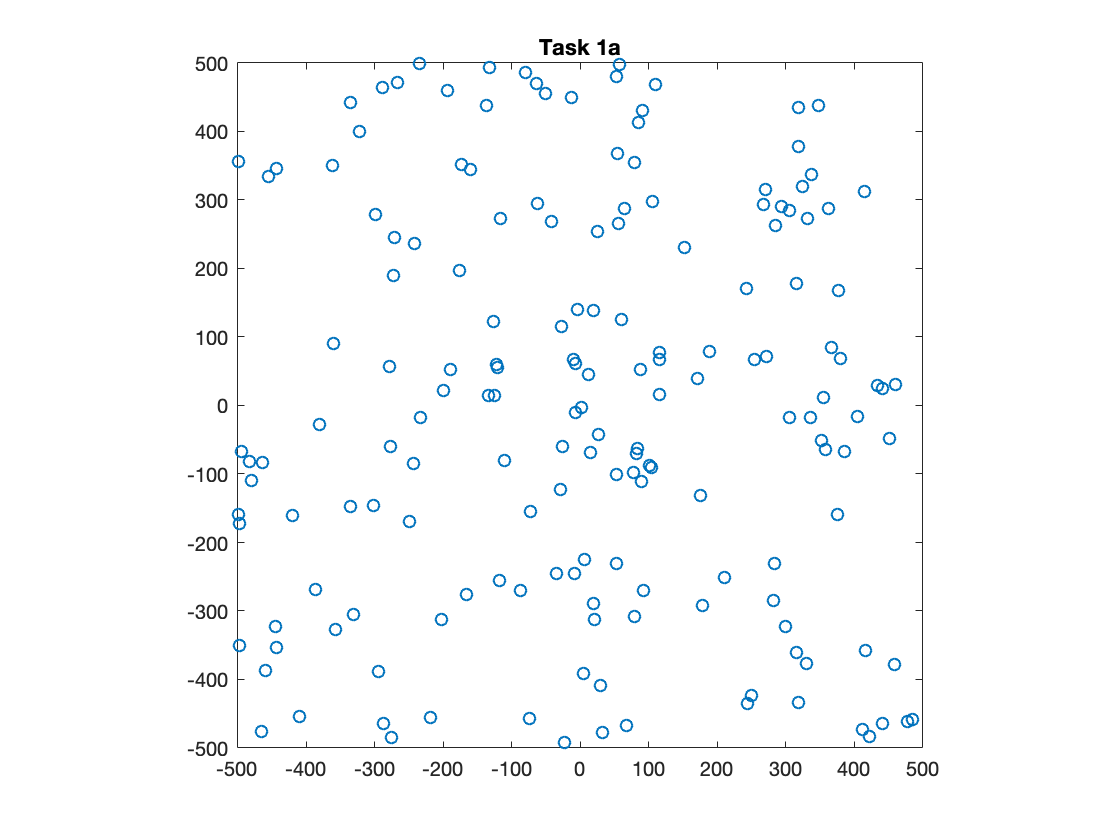

ta   = 0;                    % Resets the time
dta  = 2;                    % Time 'step'

while ta<=250
    ta = ta+dta;             % Updates time
    
    xa = xa+vxa.*dta;        % Updates x coordinate
    ya = ya+vya.*dta;        % Updates y coordinate
    ha.XData = xa;           % Plots the updated x coordinate
    ha.YData = ya;           % Plots the updated y coordinate
    drawnow 
    pause(0.005)             % Leaves a 0.05 second gap before continuing
    
    wallxa = find(abs(xa) >= 500); % Finds any x value outside the bounds
    wallya = find(abs(ya) >= 500); % Finds any y value outside the bounds
    vxa(wallxa) = vxa(wallxa)*-1;  % Flips vxa of x value outside bound
    vya(wallya) = vya(wallya)*-1;  % Flips vya of y value outside bound
    
    if mod(ta,10)==0 && ta<=250
        filename=['screenshot_taskb_' num2str(ta/10) '.png'];
        saveas(gcf,filename)
    end
end

### Task d) and f) 

We create a new figure, with the same initialisations as before. 

figure(3)                    % New figure
Nd   = randi([40 60],1,1);   % Random integer between 40 and 60
theta= 360*rand(Nd,1,1);     % Random angle
rd   = 100*rand(Nd,1,1);     % Random radius
xd   = rd.*cosd(theta);      % Polar coordinate for x
yd   = rd.*sind(theta);      % Polar coordinate for y 
hd   = plot(xd,yd,'o');      % Plots x against y 
axis manual 
axis([-500 500 -500 500])
daspect([1 1 1])
title('task d')              % New Title
vd   = 40*rand(Nd,1,1)+10;   % Random velocity between 10 and 50
vxd  = vd.*cosd(theta);
vyd  = vd.*sind(theta);
td   = 0;                    % Time
dtd  = 1;                    % Time Step

We introduce the gravitational constant $g=9\ldotp 8$, as well as setting the 'energy' of each particle, originally equal to one (this is for Task f), and we add a new figure to plot this.).

g    = 9.8;                  % Defines gravity
figure(6)                    % For task f
title('Total Energy, Task d')
en_d  = ones(Nd,1);          % Task f)
toten = plot(td,sum(en_d),'c+:');    % Task f)
hold on                      % Task f)
axis manual                  % Task f)
axis([0 170 0 (Nd+5)])       % Task f)

For 150 time points, we again recalculate the components and plot them, as well as finding the total energy in the balls.

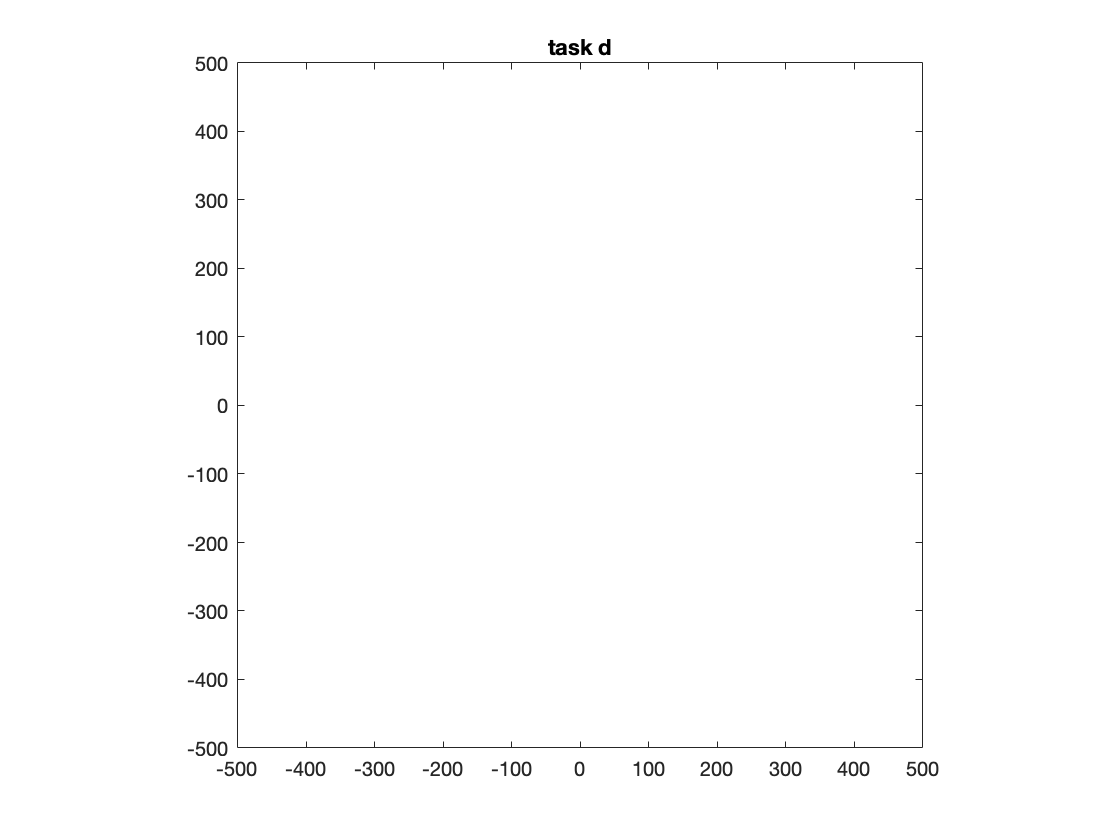

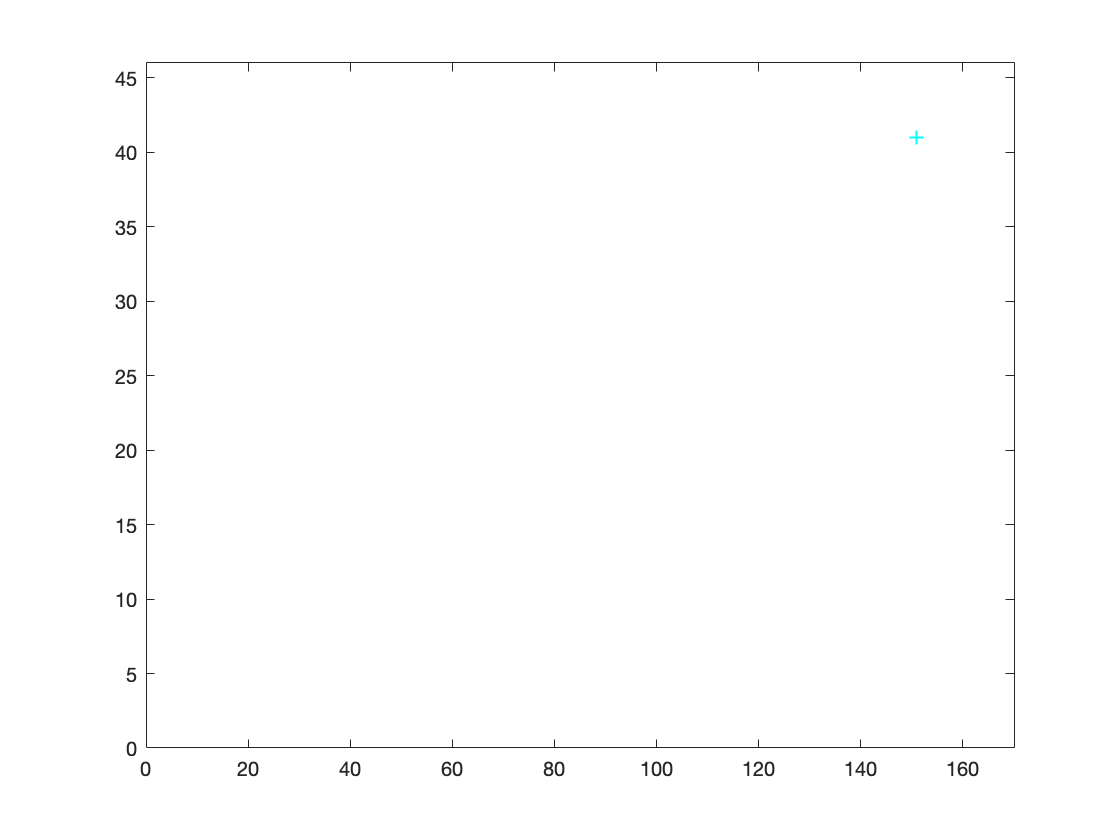

while td<=150
    td = td+dtd;             % Time ticks
    vyd=vyd-g*dtd;           % Gravity now has an effect on vertical 
                             % component of velocity of particles
    xd = xd+vxd.*dtd;
    yd = yd+vyd.*dtd; 
    hd.XData = xd;  
    hd.YData = yd;
    drawnow
    pause(0.005) 
    wallxd = find(abs(xd) >= 500);  % Finds particles outside walls
    wallyd = find(abs(yd) >= 500);  % Finds particles outside top/bottom
    vxd(wallxd) = vxd(wallxd)*-1;   % Bounces against walls
    vyd(wallyd) = vyd(wallyd)*-1;   % Bounces against bottom/top bounds
    toten.XData = td;           % Task f)
    toten.YData = sum(en_d);    % Task f)
    %sum(en_d)                   % Task f) (Included as a check)
    if mod(td,10)==0 && td<=250 % For 10, 20, 30...240, 250:
        filename=['screenshot_taskd_' num2str(td/10) '.png'];
        saveas(gcf,filename)    % Take a screenshot of the figure
    end
end

### Task e)

For the final task, involving the 'loss of energy', we again initialise the conditions. 

figure(4)                       % New figure
Ne   = randi([30 50],1,1);      % Random number
theta= 360*rand(Ne,1,1);        % Random angle
re   = 100*rand(Ne,1,1);        % Random radius
xe   = re.*cosd(theta);         % Polar x coordinate
ye   = re.*sind(theta);         % Polar y coordinate
he   = plot(xe,ye,'o');         % Plots x against y
axis manual 
axis([-500 500 -500 500])
title('Task e')
daspect([1 1 1])
ve   = 40*rand(Ne,1,1)+10;      % Random velocity between 10 and 50
vxe  = ve.*cosd(theta);         % x component of velocity
vye  = ve.*sind(theta);         % y component of velocity
te   = 0;             
dte  = 1;          
figure(5)                       % New figure for task f)
en   = ones(Ne,1);              % Energy of all particles = 1 (100%)
toten= plot(te,sum(en),'c+:');  % Plots the time against sum of energies
hold on                         
axis manual    
title('Total Energy Task e')
axis([0 170 0 (Ne+5)])          % Size of axis

Whilst the time is under 150, we introduce a method to lose 10% of each balls energy upon bouncing against a wall, as well as giving it an effect on the velocity of the ball. The final line, `sum(en)` was used to ensure the energy is decreasing over time.

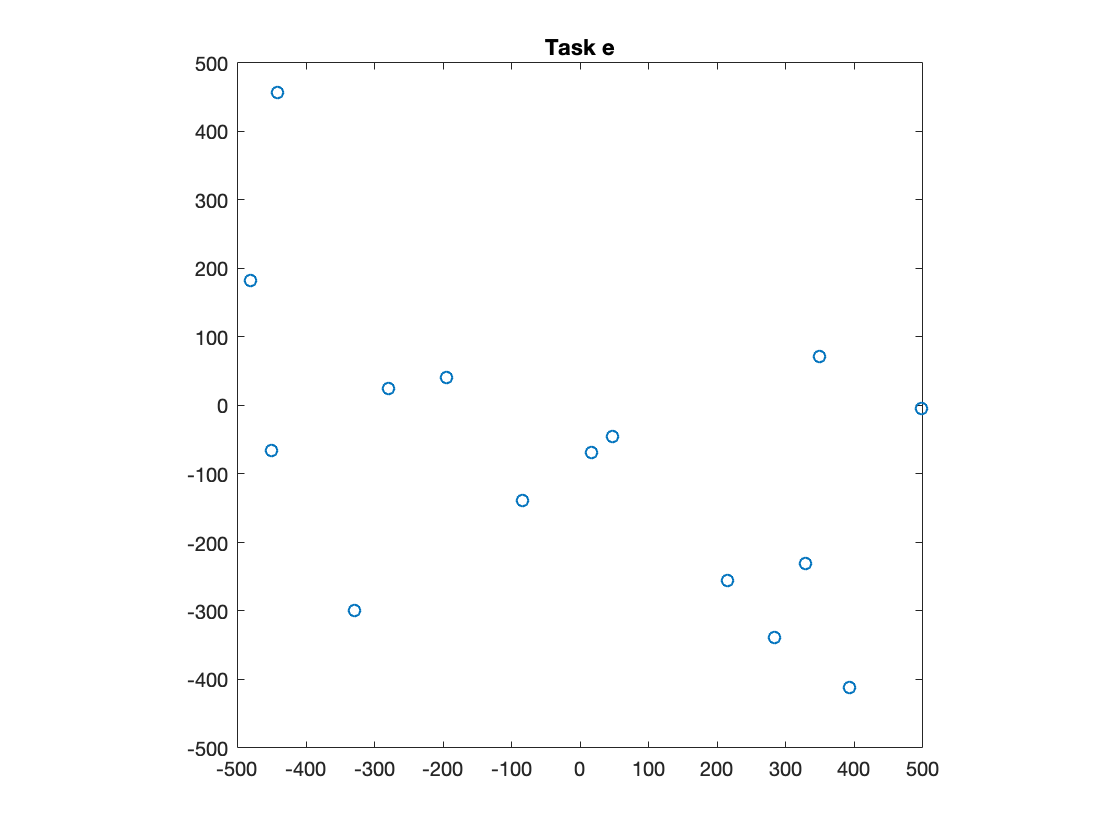

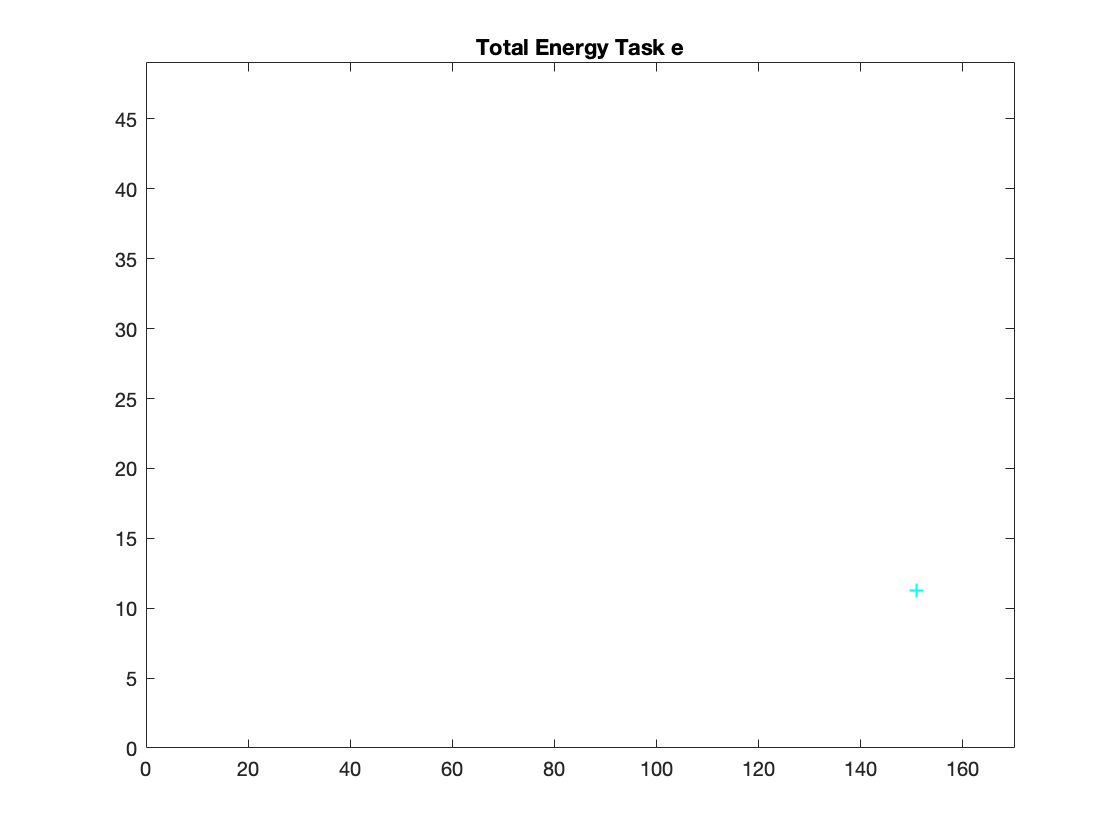

while te<=150                   
    te = te+dte;                % Time tick
    hold on     
    xe = xe+vxe.*dte;           % Updates x position  
    ye = ye+vye.*dte;           % Updates y position
    he.XData = xe;              % Plots new x coordinate
    he.YData = ye;              % Plots new y coordinate
    toten.XData = te;           % x data of task f) plot is time
    toten.YData = sum(en);      % y data of task f) plot is sum of en
    hold on
    drawnow
    pause(0.01) 
    wallxe = find(abs(xe) >= 500);  % Finds particles outside walls
    wallye = find(abs(ye) >= 500);  % Finds particles outside top/bottom
    en(wallxe)  = 0.9 * en(wallxe); % Decreases particle energy by 10%
    en(wallye)  = 0.9 * en(wallye); % Decreases particle energy by 10%
    vxe(wallxe) = vxe(wallxe)*-1.*en(wallxe);  % The energy now has an 
    vye(wallye) = vye(wallye)*-1.*en(wallye);  % effect on velocity
    %sum(en)     % Prints the sum of the energy. I used this as a check.
end

## Task Two: Symbolic Algebra Using MATLAB

Again, the task was split into subtasks:

'For this task, you use your individual cubic function y(x), found by running the cubic.exe program on Moodle (unique for everyone using student I.D.):'

- a. Find all stationary points of y(x); list their coordinates.

- b. Classify the points using the second derivative test.

- c. Plot y(x) and put small circular markets at the stationary points; put labels to indicate the classification.

- d. Find all the roots of y(x) = 0 and find the value of the integral of y(x) between the roots.

Firstly, our function is defined as $y\left(x\right)\;=\;-3x^3 +12x^2 -9x-9$. To conduct tasks in MATLAB using this function, we use the `syms x` command, before defining the function and its derivative, $\frac{\mathit{dy}}{\mathit{dx}}$ and we choose the `long` format. 

syms x
y  = (-3) * x^3 + (12)* x^2 + (-9) * x - 9   % My function, y(x)

$$y = -3\,x^{3}+12\,x^{2}-9\,x-9$$

dy = diff(y)                % Differentiates y                      

$$dy = -9\,x^{2}+24\,x-9$$

format long                 % Shows to 15 digits

With the MATLAB symbolic algebra tools, we can use `solve` to find the roots; `diff` to find the derivative (in this case, of $\frac{\mathit{dy}}{\mathit{dx}}$) and `subs` to insert the stationary point into the second derivative, in order to classify the points.

sp = double(solve(dy,0))    % Finds Stationary Points

sp =    0.451416229645136
   2.215250437021530


d2 = diff(dy)               % Second Derivative of y

$$d2 = 24-18\,x$$

cl = double(subs(d2,x,sp)); % Stationary Pt -> Second Derivative
mn = find(cl > 0);          % Finds when 2nd Deriv is positive
minimum_points = cl(mn)     % This is a minimum point.

minimum_points =   15.874507866387544


mx = find(cl < 0);          % Finds when 2nd Deriv is negative
maximum_points = cl(mx)     % This is a maximum point.

maximum_points =  -15.874507866387544


Now, we just need to plot the function, and label the stationary points. 

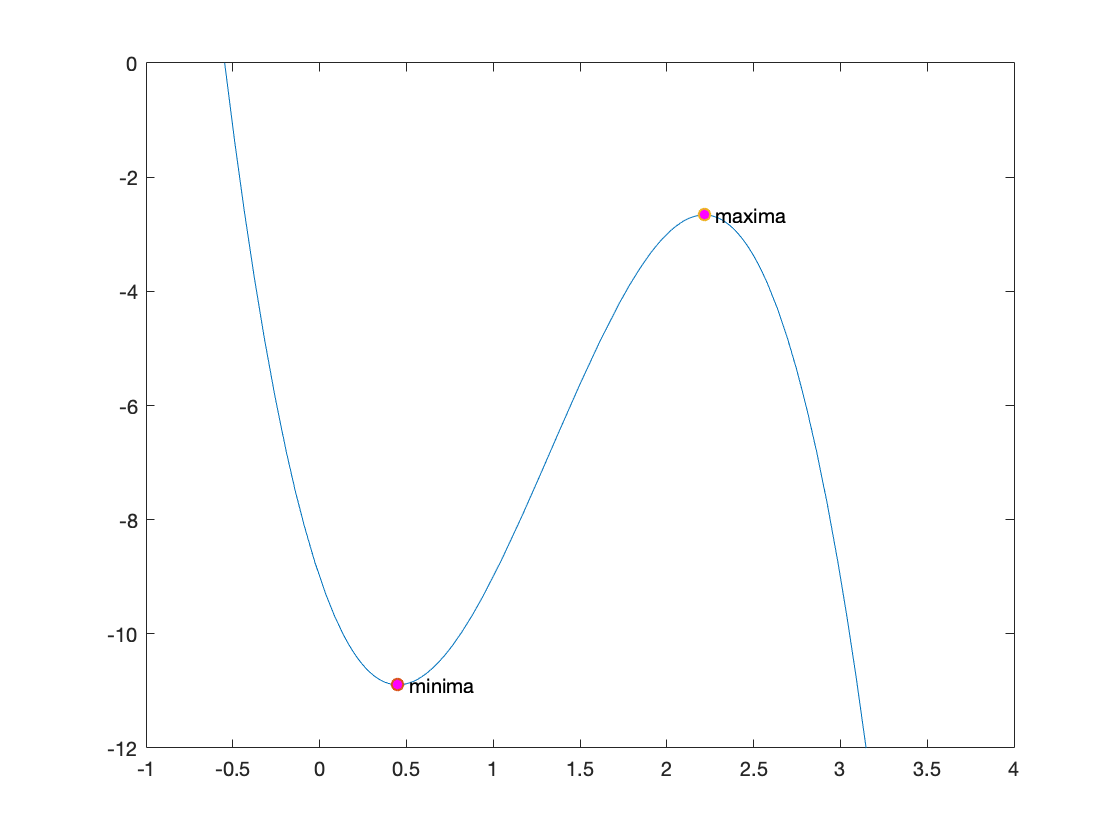

figure()                    % Opens an empty figure
fplot(y)                    % Plots y(x)
hold on                     % Holds the current plot
axis manual                 % Freezes any scaling 
axis([-1 4 -12 0])          % Sets axis limits
pp1 = subs(y,x,sp(1));      % Finds the y value of the first SP
pp2 = subs(y,x,sp(2));      % Finds the y value of the second SP 
plot(sp(1),pp1,'o','MarkerFaceColor','m')
text(sp(1),pp1,'  minima')  % Plots 'minima' at the first SP
plot(sp(2),pp2,'o','MarkerFaceColor','m')
text(sp(2),pp2,'  maxima')  % Plots 'maxima' at the second SP

% Because I have one real root, I will use the 
% first stationary point and the real root
root = double(solve(y==0))  % Finds the roots of y(x)

root =  -0.546818276884082 + 0.000000000000000i
  2.273409138442041 - 0.563821092829119i
  2.273409138442041 + 0.563821092829119i


integral = abs(double(int(y,root(1),sp(1))))  

integral =    7.497678321655504


                            % Finds int of y between the root & first SP.